Newdatatest = thingSpeakRead(1725301,ReadKey='H0UUPMUQT90CWSLF',NumPoints=200,OutputFormat='table');
temps=Newdatatest.Temperature

temps =    17.9000
   17.8000
   17.8000
   17.7000
   17.7000
   17.7000
   17.7000
   17.7000
   17.7000
   17.7000


% Solve an Autoregression Time-Series Problem with a NAR Neural Network
% Script generated by Neural Time Series app
% Created 02-Jun-2022 20:13:19
%
% This script assumes this variable is defined:
%
%   temps - feedback time series.

T = tonndata(temps,false,false);
N=200;
% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation.

% Create a Nonlinear Autoregressive Network
feedbackDelays = 1:2;
hiddenLayerSize = 10;
net = narnet(feedbackDelays,hiddenLayerSize,'open',trainFcn);

% Prepare the Data for Training and Simulation
% The function PREPARETS prepares timeseries data for a particular network,
% shifting time by the minimum amount to fill input states and layer
% states. Using PREPARETS allows you to keep your original time series data
% unchanged, while easily customizing it for networks with differing
% numbers of delays, with open loop or closed loop feedback modes.
[x,xi,ai,t] = preparets(net,{},{},T);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,x,t,xi,ai);

% Test the Network
y = net(x,xi,ai);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0068

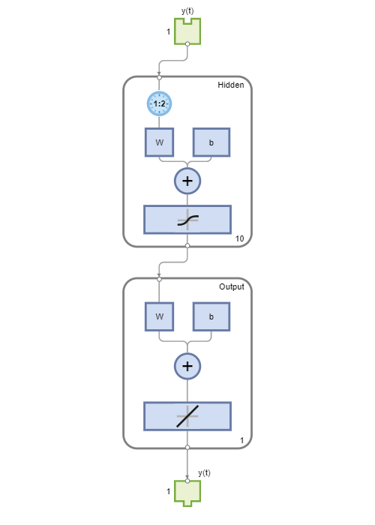


% View the Network
view(net)

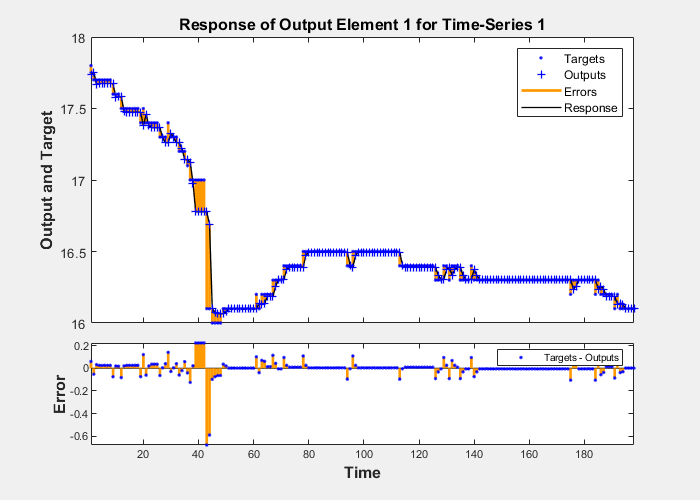


plotresponse(t,y)